% MMI - 503/603 IR Measurement Examples
% These example demonstrates how to take impulse responses an analyze it.
% Contents:
%   1. Dirac impulse response measurement
%   2. ESS impulse response measurement 

% Author: Dr. Justin D. Mathew, Ph.D
% Email: jdm423@miami.edu

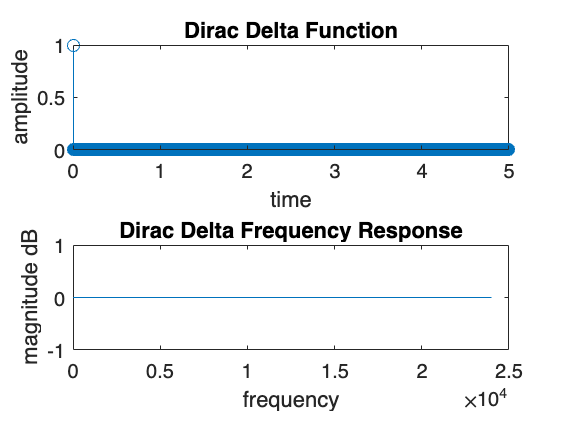

% Dirac Measurement - analyze the built in lowpass function

% create stimulus
fs = 48000;
time_length = 5; % 5 seconds
time_array = linspace(0,time_length,time_length*fs);
dirac_stimulus = dirac(time_array);
idx = dirac_stimulus == Inf;
dirac_stimulus(idx) = 1;

% analyze the frequency response of the stimulus
dirac_fft_mag = mag2db(abs(fft(dirac_stimulus, fs)));


% plot the stimulus and it's frequency response
figure;
subplot(2,1,1);
stem(time_array, dirac_stimulus);
xlabel('time');
ylabel('amplitude');
title('Dirac Delta Function');
subplot(2,1,2);
plot(1:fs/2, dirac_fft_mag(1:fs/2));
xlabel('frequency');
ylabel('magnitude dB');
title('Dirac Delta Frequency Response');

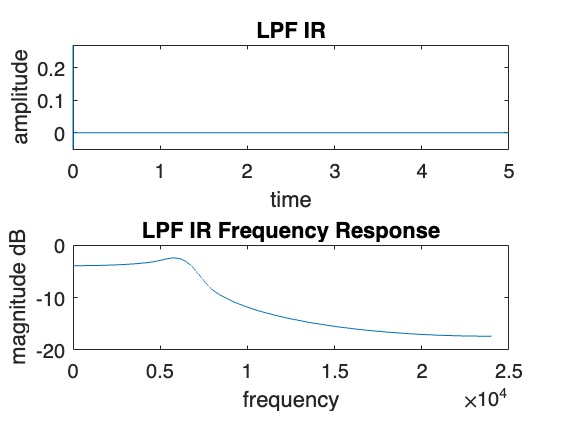


% pass the stimulus through the built in lowpass function
f_cutoff = 5000; % cutoff frequency
lowpass_ir = lowpass(dirac_stimulus, f_cutoff, fs);

% analyze the frequency response of the lowpass_ir
lowpass_ir_fft_mag = mag2db(abs(fft(lowpass_ir, fs)));

% plot the lowpass_ir and it's frequency response
figure;
subplot(2,1,1);
plot(time_array, lowpass_ir);
xlabel('time');
ylabel('amplitude');
title('LPF IR');
subplot(2,1,2);
plot(1:fs/2, lowpass_ir_fft_mag(1:fs/2));
xlabel('frequency');
ylabel('magnitude dB');
title('LPF IR (Dirac) Frequency Response');

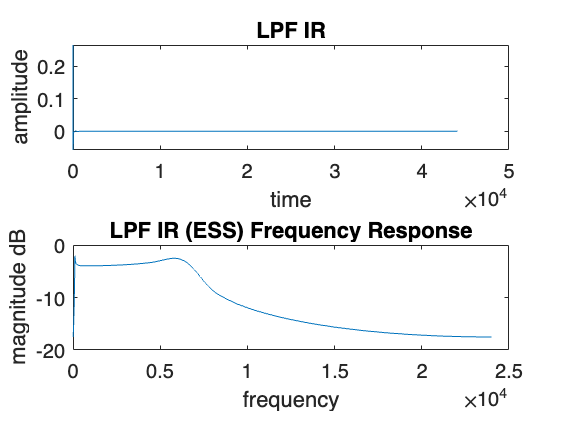

% 
time_length = 2.0;
sweep_dur = time_length; %  1.5 seconds
silence_dur = 1.0; % one second
ess_stimulus = sweeptone(sweep_dur,silence_dur, "SweepFrequencyRange", [100 20000]);

time_array = (0:numel(ess_stimulus)-1)/fs;


% Pass the stimulus through lowpass function
lowpass_ess = lowpass(ess_stimulus,f_cutoff, fs);

% Retrieve the impulse response
ess_ir = impzest(ess_stimulus, lowpass_ess);

% analyze the frequency response of the lowpass_ir
lowpass_ir_fft_mag = mag2db(abs(fft(ess_ir, fs)));


% plot the ess_ir and it's frequency response
figure;
subplot(2,1,1);
plot(ess_ir);
xlabel('time');
ylabel('amplitude');
title('LPF IR');
subplot(2,1,2);
plot(1:fs/2, lowpass_ir_fft_mag(1:fs/2));
xlabel('frequency');
ylabel('magnitude dB');
title('LPF IR (ESS) Frequency Response');